**Question 1:**

First, I load the dataset and put all the data as train data, 

myStruct = load('problem1.mat'); 
x_1= myStruct.x;
y_1 = myStruct.y;

Checking the different models for 10 diffferent values for the degree of the polynomial, printing the coresponding train risk for each model:

degree_range = 1:10; 
risk_train = zeros(length(degree_range), 1);

for D = 1:10
    [train_err, model_initial] = polyreg_initial(x_1, y_1, D);
    risk_train(D) = train_err;
    fprintf('D = %d, Training Error = %f\n', D, train_err);
end

D = 1, Training Error = 341026975080545211383808.000000
D = 2, Training Error = 146415529590681575096320.000000
D = 3, Training Error = 145752575102915163717632.000000
D = 4, Training Error = 20223799188230064046080.000000
D = 5, Training Error = 20142270692382843338752.000000
D = 6, Training Error = 1475326770339161571328.000000
D = 7, Training Error = 1474667745990768066560.000000
D = 8, Training Error = 1131342032599215767552.000000
D = 9, Training Error = 1134310498953826140160.000000
D = 10, Training Error = 1132113926146509111296.000000


Then, I load the dataset, and make a shuffled sequence of indices, to randomly divide the data to train and test sets using 2-fold cross validation:

myStruct = load('problem1.mat'); 
x_initial = myStruct.x;
y_initial = myStruct.y;

indices = randperm(numel(myStruct.x));
x_shuffled = x_initial(indices);
y_shuffled = y_initial(indices);

num_samples = numel(myStruct.x);
half_num_samples = floor(num_samples / 2);

x = x_shuffled(1:half_num_samples);
y = y_shuffled(1:half_num_samples);
xT = x_shuffled(half_num_samples+1:end);
yT = y_shuffled(half_num_samples+1:end);

Checking the different models for 10 diffferent values for the degree of the polynomial, printing the coresponding risk for each model and the plot of the polynomial fitting the data:

D = 1, Testing Error = 425491925929750735880192.000000


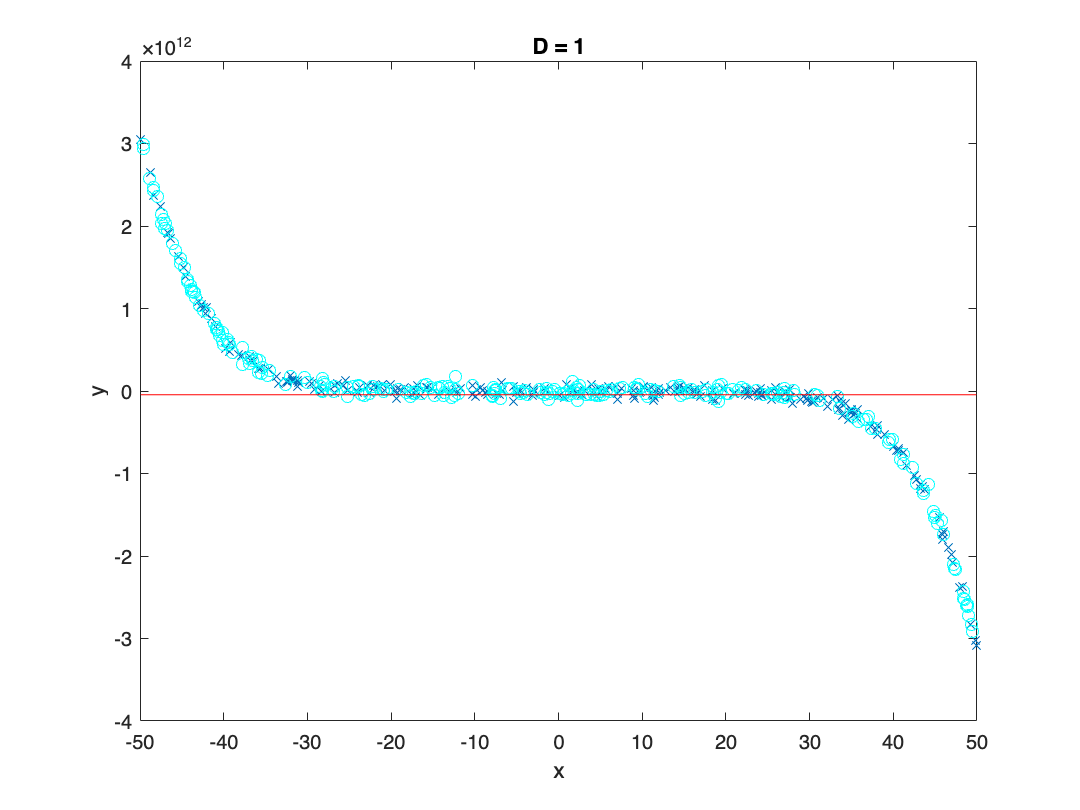

D = 2, Testing Error = 174436156070269858873344.000000


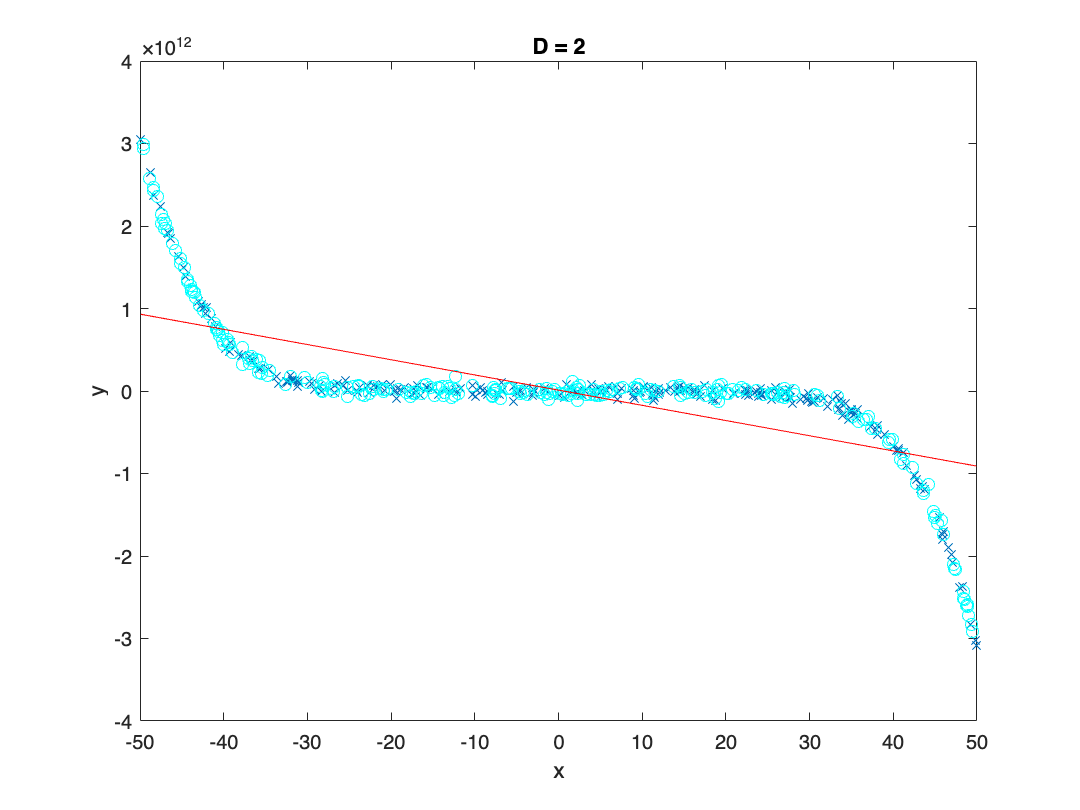

D = 3, Testing Error = 174989436322480268509184.000000


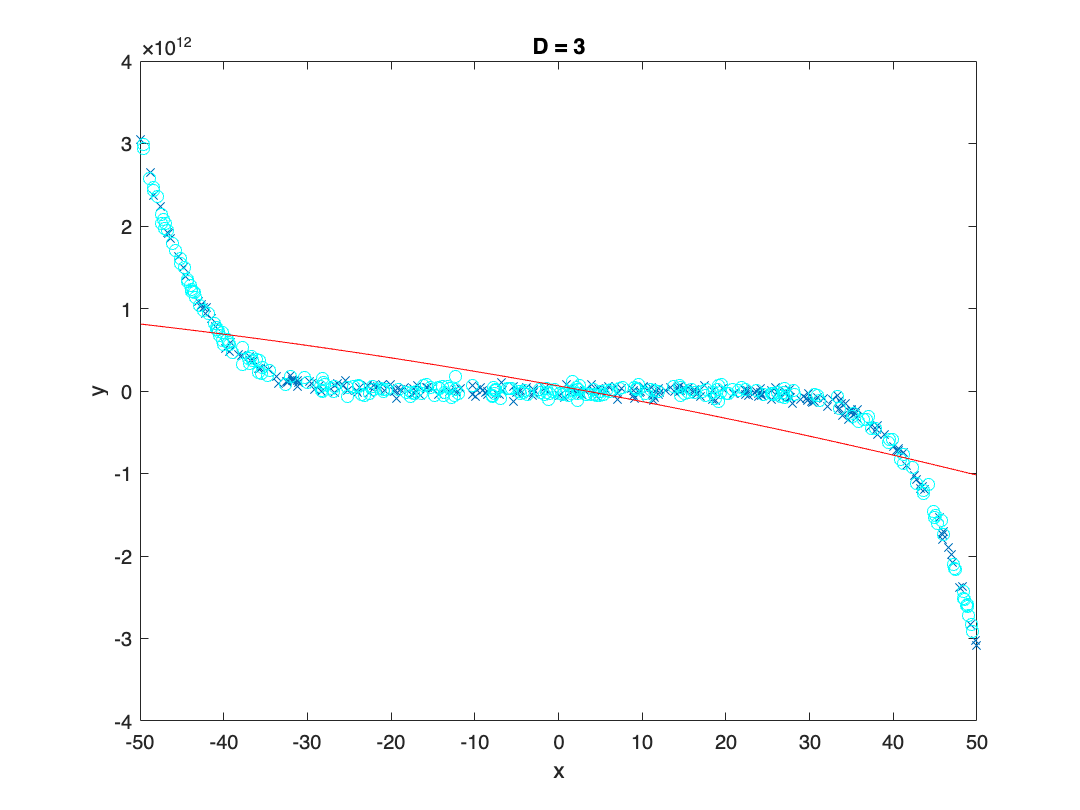

D = 4, Testing Error = 21940178987397985337344.000000


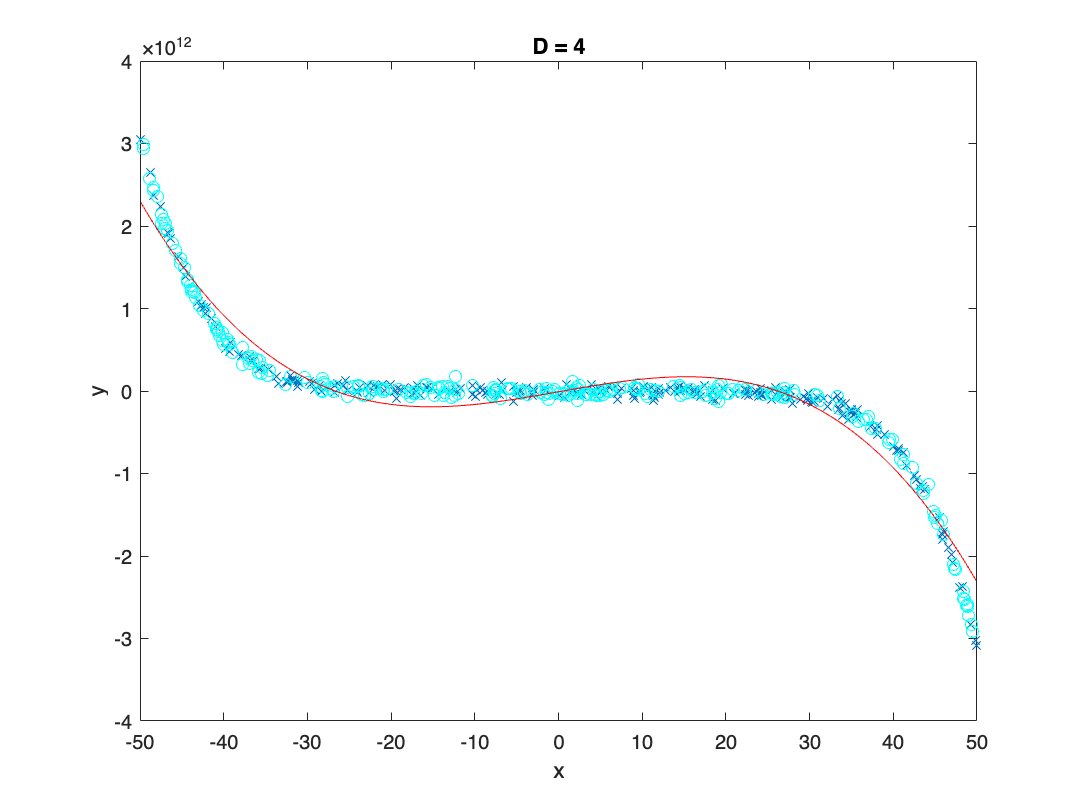

D = 5, Testing Error = 22122998714035406372864.000000


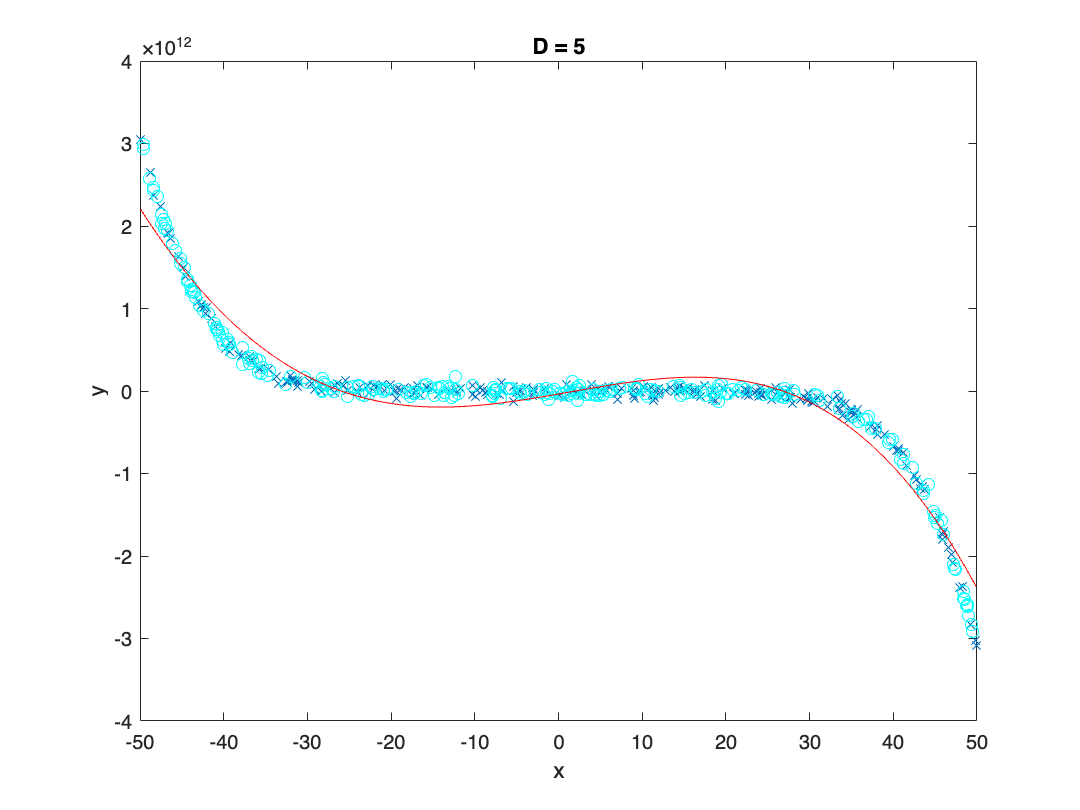

D = 6, Testing Error = 1559214838243388030976.000000


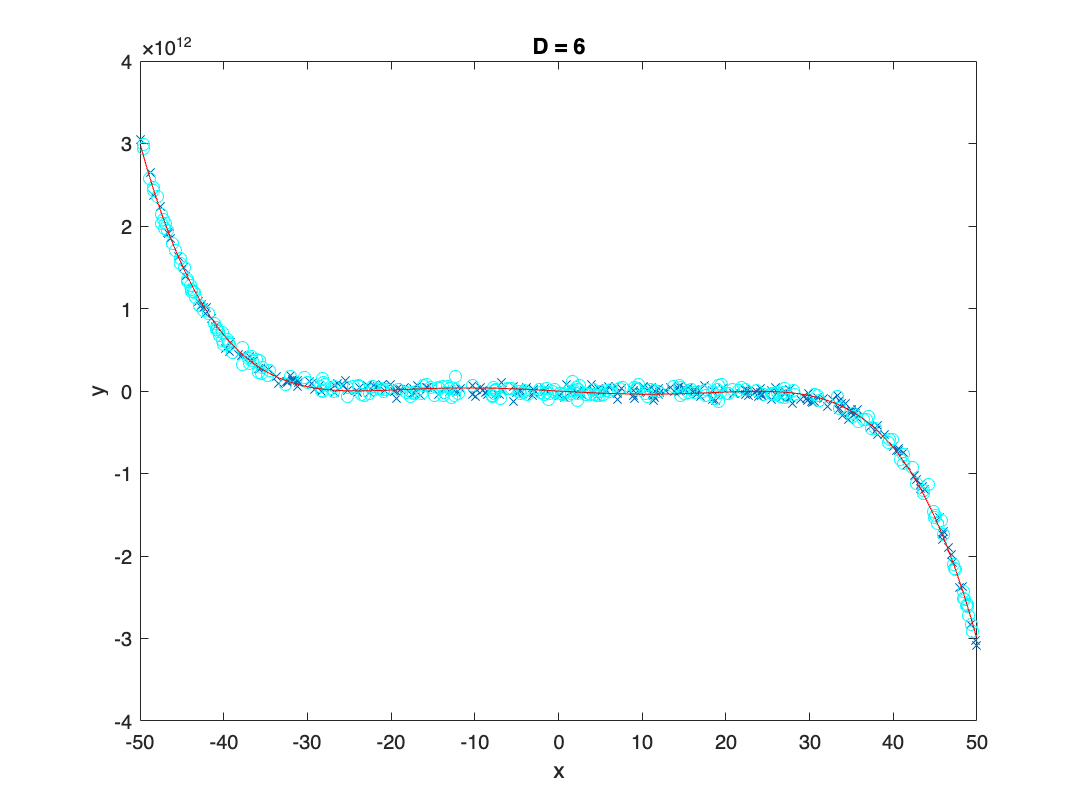

D = 7, Testing Error = 1575182947271852425216.000000


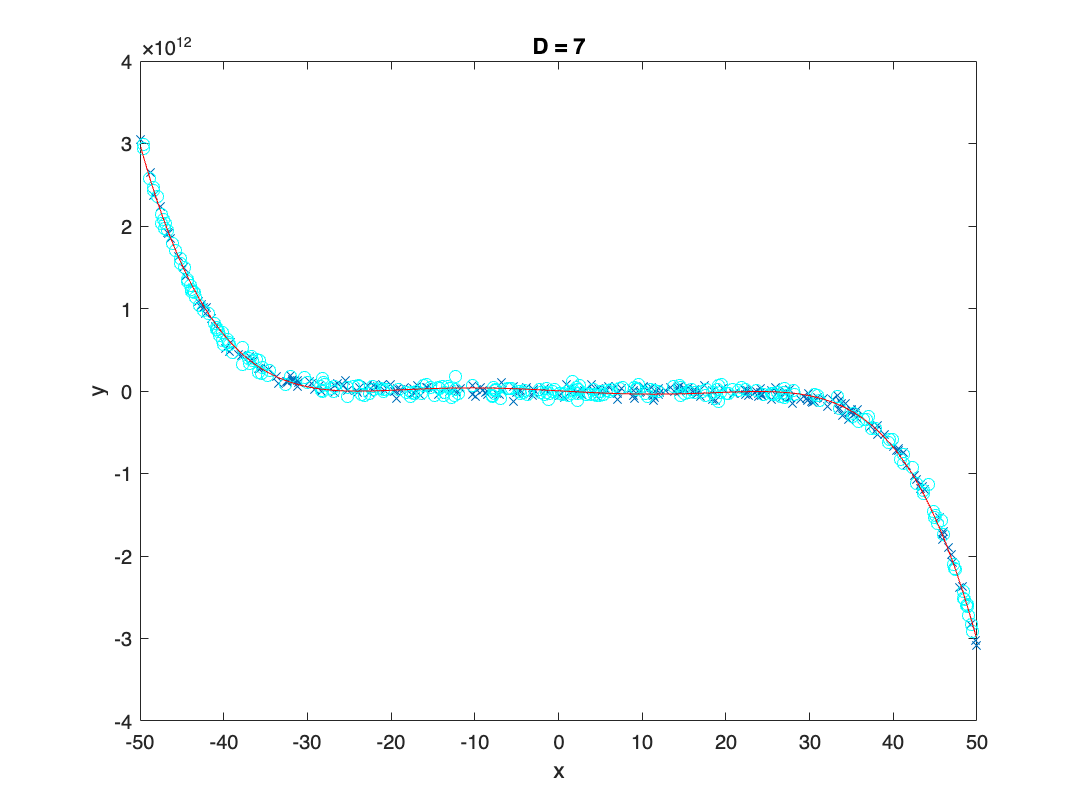

D = 8, Testing Error = 1225829557507396730880.000000


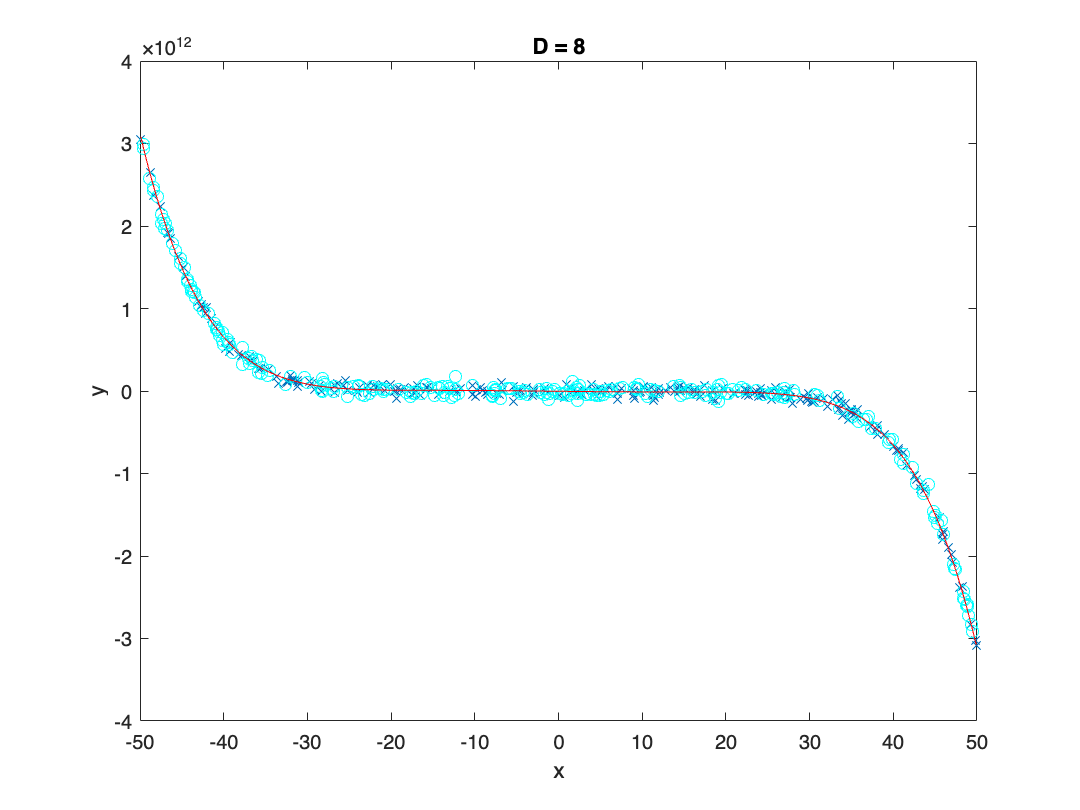

D = 9, Testing Error = 1226950310044280553472.000000


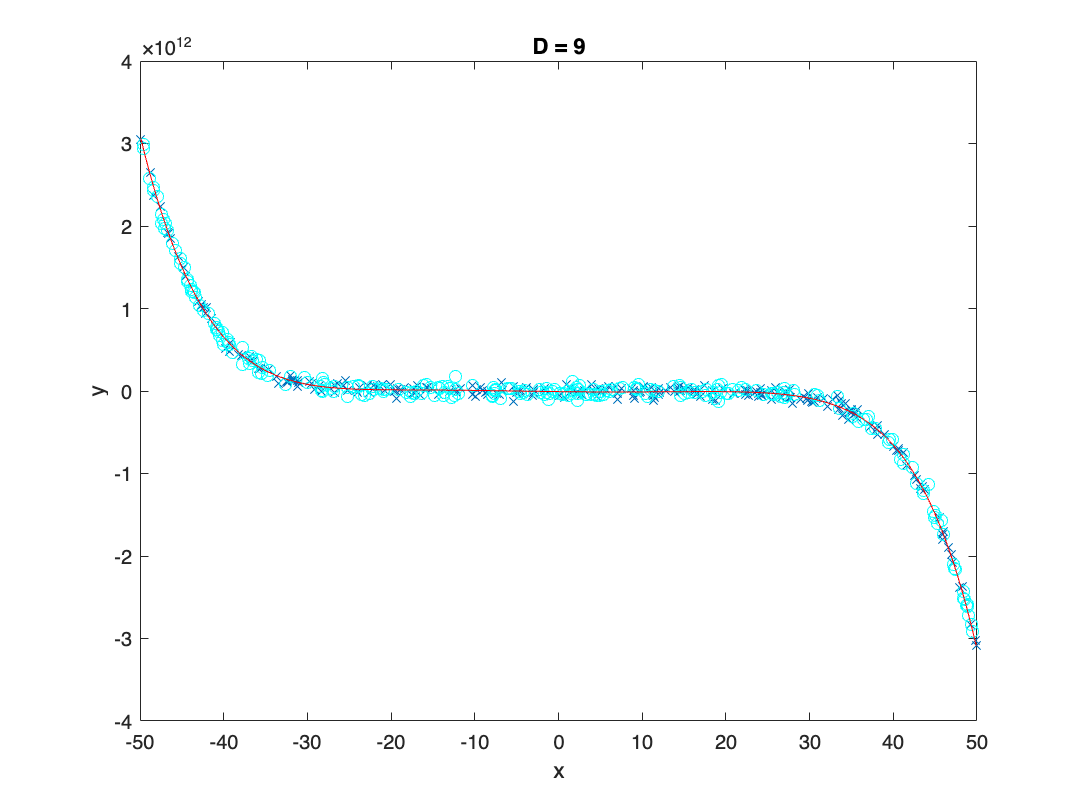

D = 10, Testing Error = 1255092582530075590656.000000


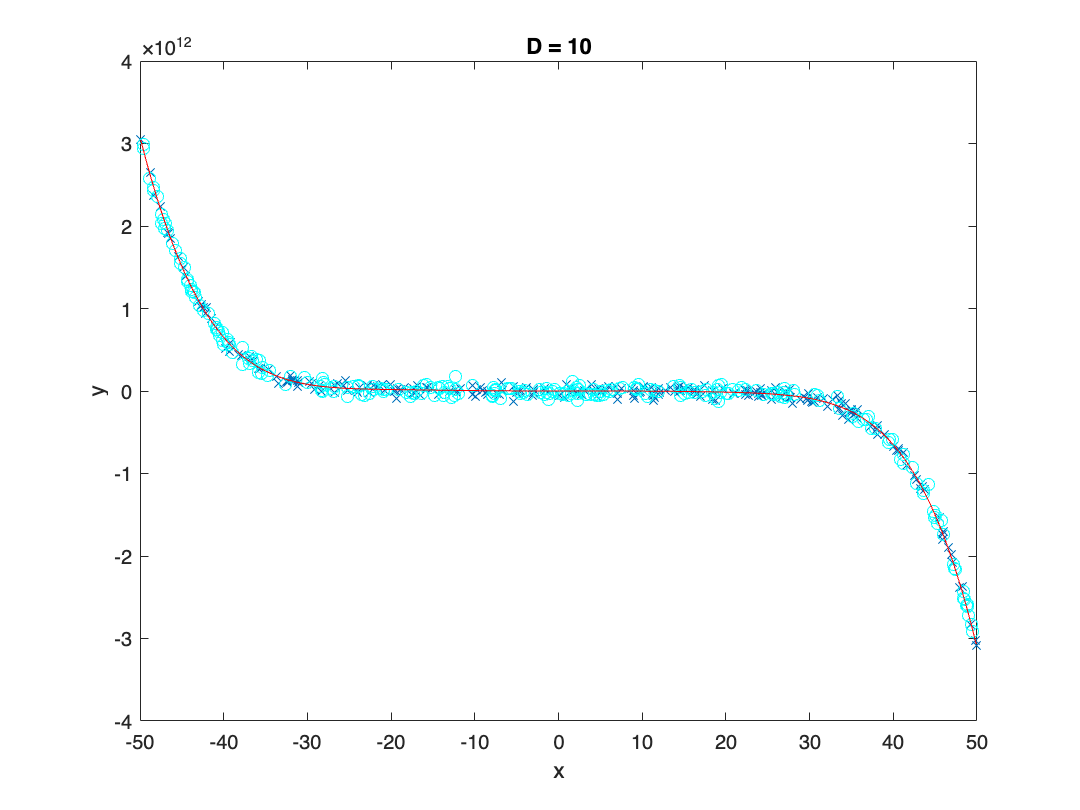

degree_range = 1:10; 
risk_vector = zeros(length(degree_range), 1);

for D = 1:10
    [err, model, errT] = polyreg(x, y, D, xT, yT);
    risk_vector(D) = errT;
    fprintf('D = %d, Testing Error = %f\n', D, errT);

    figure;
    q = (min(x):(max(x)/300):max(x))';
    qq = zeros(length(q), D);
    for j = 1:D
        qq(:, j) = q.^(D-j);
    end
    clf
    plot(x, y, 'X');
    hold on;
    plot(xT, yT, 'cO');
    xx = zeros(length(x),D);
    for i=1:D
        xx(:,i) = x.^(D-i);
    end
    model = pinv(xx)*y;
    plot(q, qq * model, 'r');
    title(['D = ' num2str(D)]);
    xlabel('x');
    ylabel('y');    

end

Now finding the best degree according to the results, we see that it is D=8:

best_degree = find(risk_vector == min(risk_vector));
fprintf('Best polynomial degree: %d\n', best_degree);

Best polynomial degree: 8


The first one is the function which computes the train risk in the first step, without using cross validation.

The second one is the function which performs polynomial fitting by calculating the emperical risk for each degree of the polynomial:

function [train_err, model_initial] = polyreg_initial(x_1, y_1, D)

xx_initial = zeros(length(x_1),D);
for i=1:D
  xx_initial(:,i) = x_1.^(D-i);
end
model_initial = pinv(xx_initial)*y_1;
train_err   = (1/(2*length(x_1)))*sum((y_1-xx_initial*model_initial).^2);

end



function [err,model,errT] = polyreg(x,y,D,xT,yT)

xx = zeros(length(x),D);
for i=1:D
  xx(:,i) = x.^(D-i);
end
model = pinv(xx)*y;
err   = (1/(2*length(x)))*sum((y-xx*model).^2);

if (nargin==5)
  xxT = zeros(length(xT),D);
  for i=1:D
    xxT(:,i) = xT.^(D-i);
  end
  errT  = (1/(2*length(xT)))*sum((yT-xxT*model).^2);
end

end

As it can be seen, if the degree of the polynomial is too low, the model does not fit the data well, which will result in great risk values. However, by increasing the degree of the polynomial, the train loss will continously decrease. But it is not always beneficial because if we set the degree too large, it will result in overfitting. So we check the test loss to make sure that the polynomial is fitting the data well without overfitting, which happens in D=7.